EVERYTHING IS IN MILLIMETERS OR NEWTONS OR MEGAPASCALS

Constant Variables

train_location_initial = [-856 -680 -516 -340 -176 0];  % location of train initially
length_bridge = 1200;  % length of the bridge

train_locations = zeros(856 + length_bridge,6);             % all locations of train (1 row is one set of locations) 
for i = 1:856+length_bridge                                 % produces all possible locations of train 
    train_locations(i, :) = train_location_initial + ones(1,6) .* (i-1);
end

E = 4000;
mu = 0.2;
S_tens =  30;
S_comp = 6;
T_board = 4;
T_glue= 2;


Variables to Edit Based on Design (DON'T EDIT ANYTHING ELSE)

loads_from_train = [400/6 400/6 400/6 400/6 400/6 400/6];  % CHANGE THIS FOR EACH LOAD CASE 
% USE NEWTONS


y_bar = ones(1, length_bridge+1).*41.431;  % CHANGE THIS FOR NEW DESIGNS
I = ones(1, length_bridge+1).*418352;  % CHANGE THIS FOR NEW DESIGNS
height = ones(1, length_bridge+1).*76.27;  % CHANGE THIS FOR NEW DESIGNS
b_glue = ones(1, length_bridge+1).*12.54;  % CHANGE THIS FOR NEW DESIGNS
b_centroid = ones(1, length_bridge+1).*2.54;  % CHANGE THIS FOR NEW DESIGNS
diaphragm_dist = 100; % constant distance between diaphragms

Q_centroid = ones(1, length_bridge+1).*4623.7; % this is where shear force will be max
Q_glue = ones(1, length_bridge+1).*4343.9; % this is at the glue, might need more than 1 glue location

y_top = height - y_bar;  % for stress calcs
y_bottom = y_bar;  % for stress calcs

% must manually input values for thin plate buckling depending on design
S_buck1 = (4 * pi^2 * E)/(12*(1-mu)^2)*(2*1.27/80)^2;   % change the last squared term (t/b)^2
S_buck2 = (0.425 * pi^2 * E)/(12*(1-mu)^2)*(2*1.27/20)^2;   % change the last squared term (t/b)^2;
S_buck3 = (6 * pi^2 * E)/(12*(1-mu)^2)*(1.27/(100-1.27-78.9))^2;   % change the last squared term (t/b)^2
T_buck = (5 * pi^2 * E)/(12*(1-mu)^2)*((2*1.27/80)^2-(2*1.27/diaphragm_dist));  % change the last squared term (t/h)^2-(t/a)^2


Support Reactions

support_reactions = zeros(length_bridge + 856, 2); % returns two columns, first is left support, second is right support

for i = 1:856+length_bridge              
    sum_for_forces = 0;  % restarts calculations for each new location
    sum_for_moments = 0;
    for j = 1:6
        if(1200 >= train_locations(i,j)) && (train_locations(i,j) >= 0)   % Only considers loads that are actually on the bridge
            sum_for_forces = sum_for_forces + loads_from_train(1,j);
            sum_for_moments = sum_for_moments + train_locations(i,j) * loads_from_train(1,j); 
        end
    b = sum_for_moments / length_bridge;
    a = sum_for_forces - b;
    support_reactions(i,:) = [a b];  % returns the support reactions for the i-th train location
    end
end


SFD and BMD

SFD = zeros(length_bridge+856, length_bridge+1);
BMD = zeros(length_bridge+856, length_bridge+1);
for i = 1:length_bridge+856  % Calculating SFD for th   e i-th train location
    a = support_reactions(i,1);  % support reaction on the left

    for j = 1:length_bridge+1
        sum_forces = a;
        for k = 1:6
            if(train_locations(i,k) <=1200 && train_locations(i,k) >= 0 && (j-1) >= train_locations(i,k)); % if current location is further than train location
                sum_forces = sum_forces - loads_from_train(1,k); %
            end
        end   

        if(j == length_bridge+1) % for the last location of the bridge
            SFD(i,j) = 0;   % the shear force is always equal to zero
        else
            SFD(i,j) = sum_forces; % else the shear force equal the sum calculated
        end

    end
    BMD(i,2:length_bridge) = cumsum(SFD(i,1:length_bridge-1)); % approximates BMD using riemann sums
end


MAX SFD and BMD Values AT THAT BRIDGE LOCATION

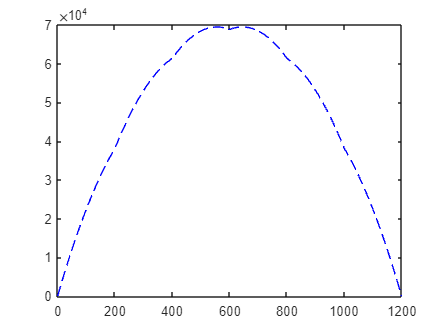

sfd_max = zeros(1, length_bridge+1);
sfd_max = max(abs(SFD(:,:)));
sfd_max(1,length_bridge+1) = sfd_max(1,length_bridge); % sets the last sfd to the previous one so graph doesn't look terrible 
bmd_max = zeros(1, length_bridge + 1);
bmd_max(1,:) = max(BMD(:,:)); % get BMD envelope

plot(linspace(0,length_bridge,length_bridge+1), bmd_max , "b--")

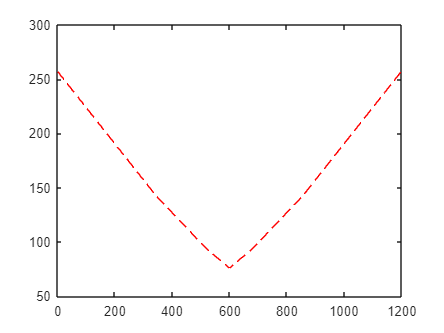


plot(linspace(0,length_bridge,length_bridge+1), sfd_max, "r--")
xlim([0 length_bridge])

Stresses on the Cross Section

flex_bott = bmd_max .*  y_bottom ./ I;  % tension
flex_top = bmd_max .*  y_top ./ I;  % compression

shear_centroid = Q_centroid .* sfd_max ./ (I .* b_centroid);  % max shear on matboard, which resists 4MPa
shear_glue = Q_glue .* sfd_max ./ (I .* b_glue);  % max shear on glue, which resists 2MPa


Factors of Safety

FOS_tens = S_tens ./ max(flex_bott);  % since minimum will govern
FOS_comp = S_comp ./ max(flex_top);
FOS_shear = T_max ./ max(shear_centroid);
FOS_glue = T_gmax ./ max(shear_glue);

FOS_buck1 = S_buck1 / 6;  % if FOS > 1, then it doesn't matter since it'd fail in compression before buckling
FOS_buck2 = S_buck2 / 6;
FOS_buck3 = S_buck3 / 6;

FOS_buck = T_board / T_buck;

Print These Variables for Recording

FOS_tens

FOS_tens = 4.3621

FOS_comp

FOS_comp = 1.0375

FOS_shear

FOS_shear = 3.5769

FOS_glue

FOS_glue = 9.3985


FOS_buck1

FOS_buck1 = 3.4546

FOS_buck2

FOS_buck2 = 5.8728

FOS_buck3

FOS_buck3 = 21.0844

FOS_buck

FOS_buck = -0.0064


M_fail_tension = FOS_tens * max(bmd_max)

M_fail_tension = 3.0293e+05

M_fail_compression = FOS_comp * max(bmd_max)

M_fail_compression = 7.2049e+04

% M_fail

V_fail_shear = FOS_shear * max(sfd_max)

V_fail_shear = 919.2760

V_fail_buck = FOS_buck * max(sfd_max)

V_fail_buck = -1.6398

V_fail_glue = FOS_glue * max(sfd_max)

V_fail_glue = 2.4154e+03